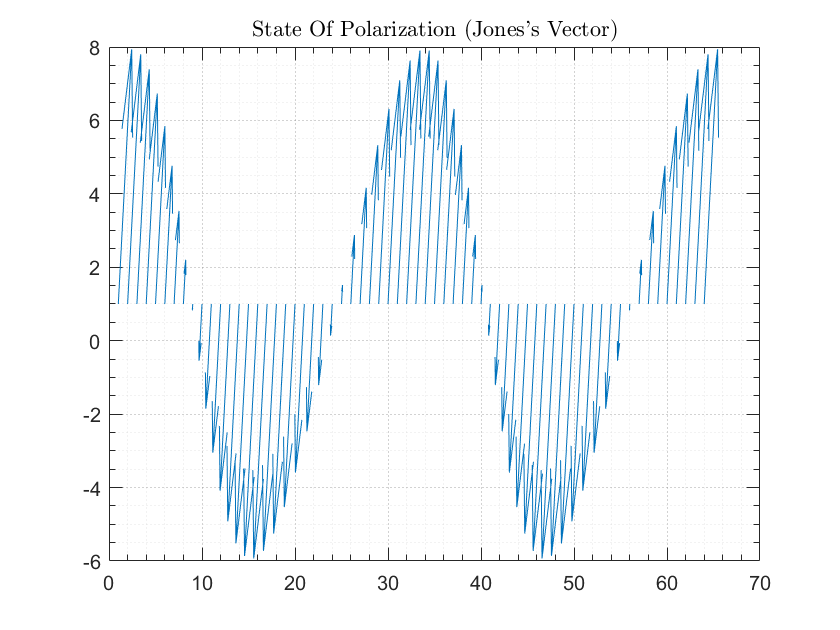

% Electric field amplitudes
E0x = 10;
E0y = 10;

% Phase of Ey
phi_x = 0;
phi_y = 0.5*pi;

%Grid points
N = 64;

%Calculations for z = 0
wt = linspace(0,4*pi,N);

%Electric fields
Ex = E0x*exp(1j*wt + phi_x);
Ey = E0y*exp(1j*wt + phi_y);

quiver(real(Ex), real(Ey))
title("State Of Polarization (Jones's Vector)", "Interpreter","latex")
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid